# Determine source of toll charges

`taxiTable = addTollSource(taxiTable)` adds the feature `TollSource` to `taxiTable`. This feature is a categorical array indicating the source of the toll charges. Known toll amounts for each source are compared to the charged amount to determine the source(s).

#### Description of toll sources

- `VN`: Verrizano Narrows

- `HH`: Henry Hudson

- `CBGH`: Cross-Bay Memorial and Gil Hodges Memorial

- `MTA_Other`: All other Metro Transit Authority (Bronx-Whitestone, Throgs Neck, and Robert F. Kennedy bridges; Hugh L. Carey and Queens Midtown tunnels) 

- `NYPA`: Ney York Port Authority (Lincoln & Holland tunnels, the George Washington, Bayonne & Goethals bridges, and the Outerbridge Crossing). These tolls are paid only when entering NYC from surrounding areas.

- `NoToll`: No toll was charged

- `OtherToll`: A toll was charged that does not correspond to a known amount or combination.

####         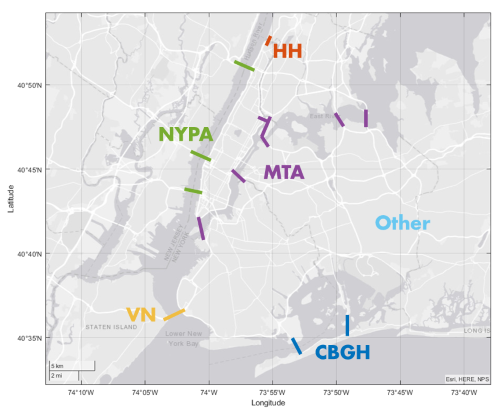

#### Scenarios to consider

Multiple toll sources: Multiple tolls may be charged in a single trip. Typically, this is `MTA_Other` and either `VN`, `HH`, or `CBGH`. Each combination appears as a separate category: `'CBGH_MTA_Other','HH_MTA_Other','VN_MTA_Other','NYPA_MTA_Other'`.

Multiple rates: Toll charge can vary based on time of day (peak/off-peak) as well as method of payment (cash/EZ-pass). The rates for each toll source are merged into a single rate that is unique for each source.

Double charges: Toll charge is exactly double a known amount. It is common to be charged a double toll when the trip takes a taxi outside it's assigned area. The category corresponding to the single charge amount is assigned.

Toll Increases: MTA tolls were raised on 3/22/2015; NYPA tolls were raised on 12/6/2015. The algorithm assigns the same category to both rates.

Multiple possibilities: Two toll sources can create the same toll charge:

- $7.50: MTA (other) cash toll and double `CBGH` cash toll.

- $10.66: Single VN EZ-pass bridge cash toll and double MTA (other) EZ-pass toll.

For trips with a $7.50 toll charge, if the pick up and drop off locations were both above the CBGH bridges, it is assumed the toll source was MTA (other). Otherwise, the toll source is assumed to be CBGH.

For trips with a $10.66 toll charge, if either the pick up or drop off was in Staten Island, it is assumed the toll source was the VN bridge, which connects Brooklyn and Staten Island. Otherwise, the toll source is assumed to be MTA (other). 

Possible errors: NYPA Cash amounts ($14,$15)

#### Sources

- [http://www.mta.info/news/2012/12/19/mta-adopts-fare-and-toll-increases-2013](http://www.mta.info/news/2012/12/19/mta-adopts-fare-and-toll-increases-2013)

- [http://www.mta.info/news-fares-tolls-board-subway/2015/01/22/customers-who-use-mta-most-will-see-lowest-increases](http://www.mta.info/news-fares-tolls-board-subway/2015/01/22/customers-who-use-mta-most-will-see-lowest-increases)

- [https://patch.com/new-jersey/hoboken/toll-hikes-take-effect-nj-sunday-includes-gwb-lincoln-holland-tunnels-0](https://patch.com/new-jersey/hoboken/toll-hikes-take-effect-nj-sunday-includes-gwb-lincoln-holland-tunnels-0)

function taxiTable = addTollSource(taxiTable)
taxiTable.TollSource = taxiTable.Tolls;

Define toll sources and identifying toll charges

% Names of the various toll sources to classify
sources = {'NoToll','CBGH','HH','VN','MTA_Other','CBGH_MTA_Other','HH_MTA_Other','VN_MTA_Other','NYPA','NYPA_MTA_Other','OtherToll'};

% Corresponding rate that will be used to identify each source. 
% The EZ-pass off-peak rate valid on Jan 1, 2015 is used.
tolls = [0,2,2.44,10.66,5.33,7.33,7.77,15.99,9.75,15.08];

Determine source of identical toll amounts

% Use latitude to determine source of $7.50/$8 tolls 
% If pick up and drop off locations are North of CBGH, assign MTA_Other rate
taxiTable.TollSource(ismember(taxiTable.TollSource,[7.50,8]) & ...
    taxiTable.PickupLat > 40.617 & taxiTable.DropoffLat > 40.617) = 5.33; % 40°37'N

% Use longitude to determine source of $10.66/$15/$11.08/$16 tolls 
% If pick up and drop off locations are East of VN, assign MTA_Other rate
taxiTable.TollSource(ismember(taxiTable.TollSource,[10.66,15,11.08,16]) & ...
    taxiTable.PickupLon > -74.05 & taxiTable.DropoffLon > -74.05) = 5.33; % 74°03'W

Convert multiple rates to the corresponding EZ-pass off-peak rate captured in `tolls`. 

% List all known toll charges for each source
tollconversions = {{2,[4,3.75,7.50,2.08,4.16,8.00]},...         % 'CBGH'
                   {2.44,[4.88,5,10,2.54,5.08,5.50,11]},...     % 'HH'
                   {10.66,[15,11.08,16]},...                    % 'VN'
                   {5.33,5.54},...                              % 'MTA_Other'
                   {7.33,7.62},...                              % 'CBGH_MTA_Other'
                   {7.77,8.08},...                              % 'HH_MTA_Other'
                   {15.99,16.62},...                            % 'VN_MTA_Other'
                   {9.75,[11.75,10.50,12.50]}, ...              % 'NYPA'
                   {15.08,[17.08,16.04,18.04,15.29,17.29]}};    % 'NYPA_MTA_Other'

% For each source, convert charges to the right of the comma into the value to the left.
for i = 1:length(tollconversions)
    taxiTable.TollSource(ismember(taxiTable.TollSource,tollconversions{i}{2})) = tollconversions{i}{1};
end    

% Change all unknown toll charges to NaN.
taxiTable.TollSource(~ismember(taxiTable.TollSource,tolls)) = NaN;  % 'OtherToll'

Convert `TollSource` to a categorical and replace the amounts with source names 

taxiTable.TollSource = categorical(taxiTable.TollSource,[tolls,NaN],sources);

end